# Introduction

Implementation of Spiliopoulos' inter-bank reserves model with multiplicative common noise


$$\mathrm{d}X_t^i = a_{i}\left(\bar{X}_t-X_t^i\right) \mathrm{d}t + \sigma_{i}\mathrm{~d}\widetilde{W}^{i}_{t} $$


where $\mathrm{~d}\widetilde{W}_{t}^{i}=\rho (\exp{X_{t}^{i}})^{\gamma_{1}} \mathrm{~d}W_{t}^{0}+ \sqrt{1-\rho^2} ({\exp{X_{t}^{i}}})^{\gamma_{2}}  \mathrm{~d} W_{t}^{i}$, with $W^{i}$ the individual noises and $W^{0}$ the common noise.

% Add paths for SDETools
addpath 'C:\Users\Harry\OneDrive - Imperial College London\Imperial\Project\SDETools-master\SDETools'
addpath 'C:\Users\Harry\OneDrive - Imperial College London\Imperial\Project\SDETools-master\Simulations\Spiliopoulos2017'

Homogeneous banks ($a = 1, \sigma = 1$), no common noise. $N = 10$.


$$\mathrm{d}X_t^i = \left(\bar{X}_t-X_t^i\right) \mathrm{d}t + \mathrm{~d}W^{i}_{t}$$


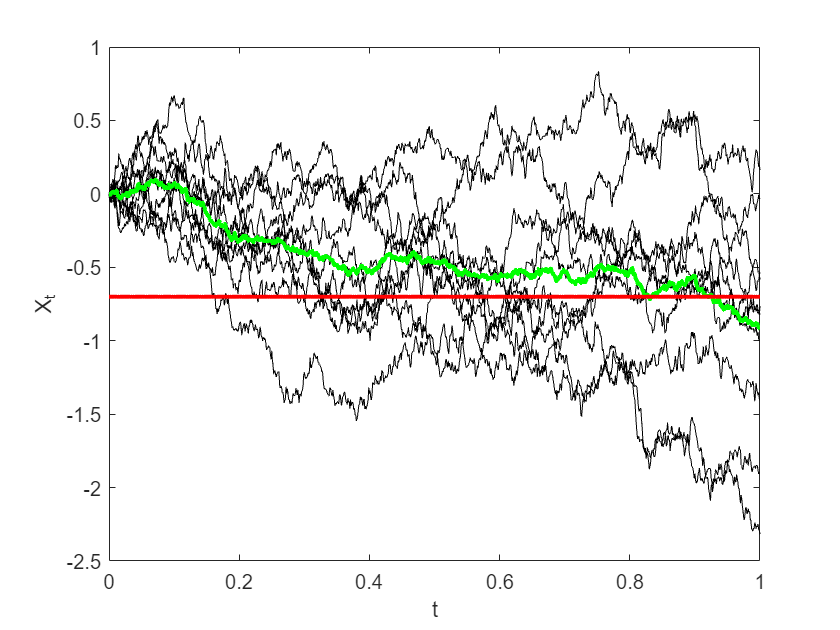

baseline = model(10, ones(10, 1), ones(10, 1));
baseline = baseline.sde_euler;
plot_trajectory(baseline);

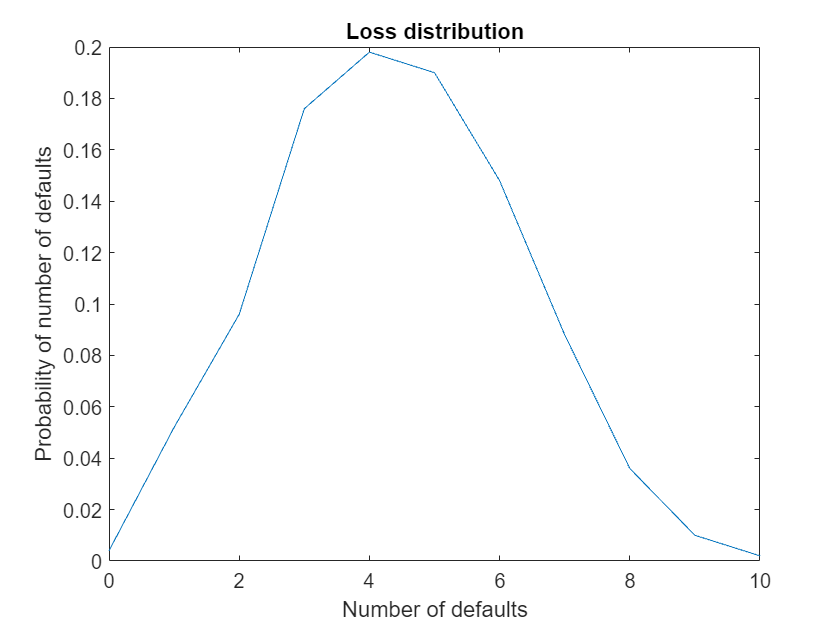

baseline.plot_loss;

Multiplicative but no common noise: $\rho = 0$;$\sqrt{\exp{X_{t}^{i}}}  \mathrm{~d} W_{t}^{i}$

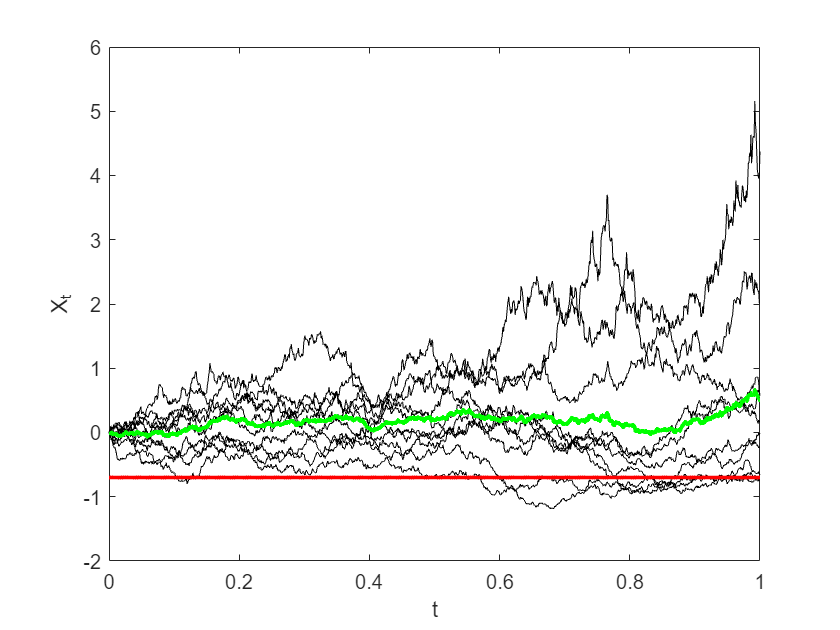

baseline_mn = baseline.multiplicative_common_noise(0, 0.5, 0.5);
baseline_mn = baseline_mn.sde_euler;
baseline_mn.plot_trajectory;

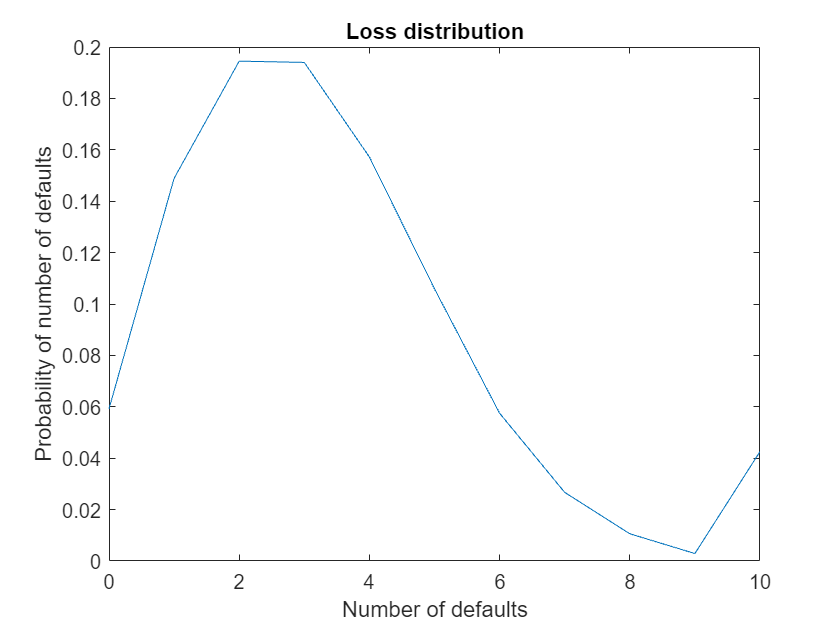

plot_loss(baseline_mn, 10000);

Multiplicative and common noise: $\rho = 0.5$, $\gamma_{1} = \gamma_{2} = 0.5$; 

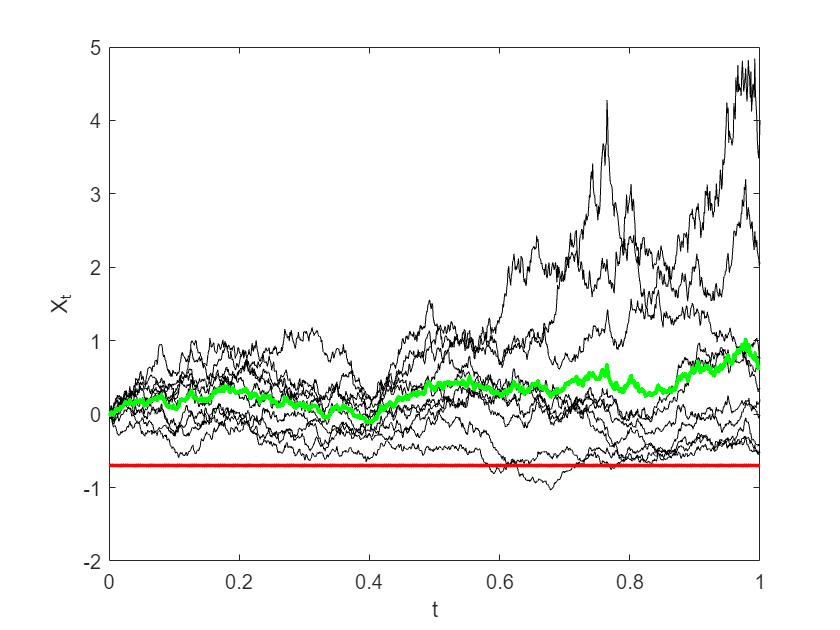

baseline_mcn = baseline.multiplicative_common_noise(0.5, 0.5, 0.5);
baseline_mcn = baseline_mcn.sde_euler;
baseline_mcn.plot_trajectory;

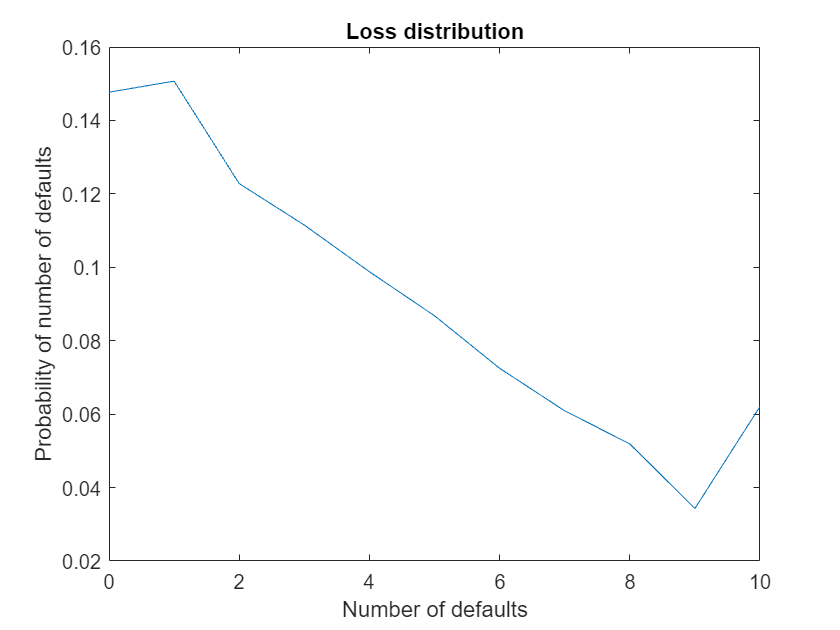

plot_loss(baseline_mcn, 10000);

Multiplicative and common noise: $\rho = 0.9$

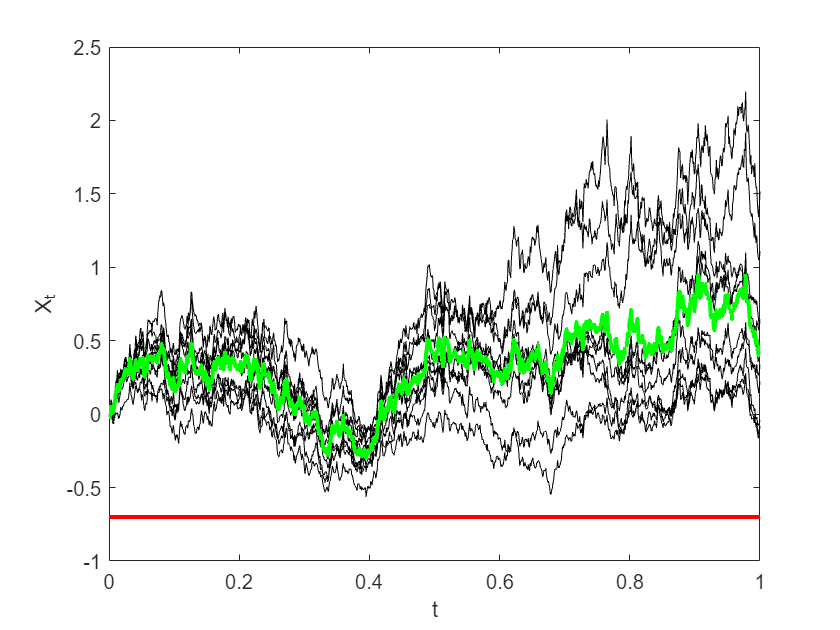

baseline_mcn2 = baseline.multiplicative_common_noise(0.9, 0.5, 0.5);
baseline_mcn2 = baseline_mcn2.sde_euler;
baseline_mcn2.plot_trajectory;

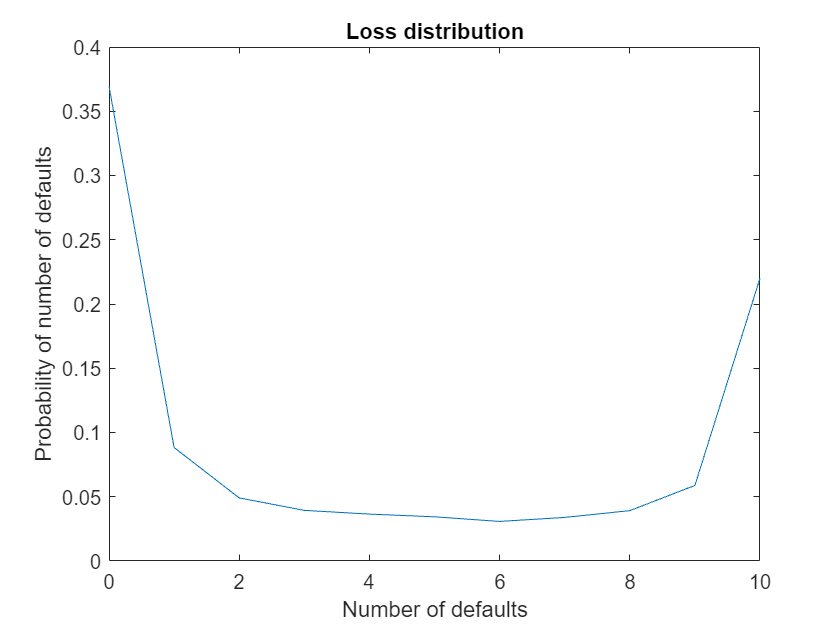

plot_loss(baseline_mcn2, 10000);

Experiment with inverse exponential multiplicative noise

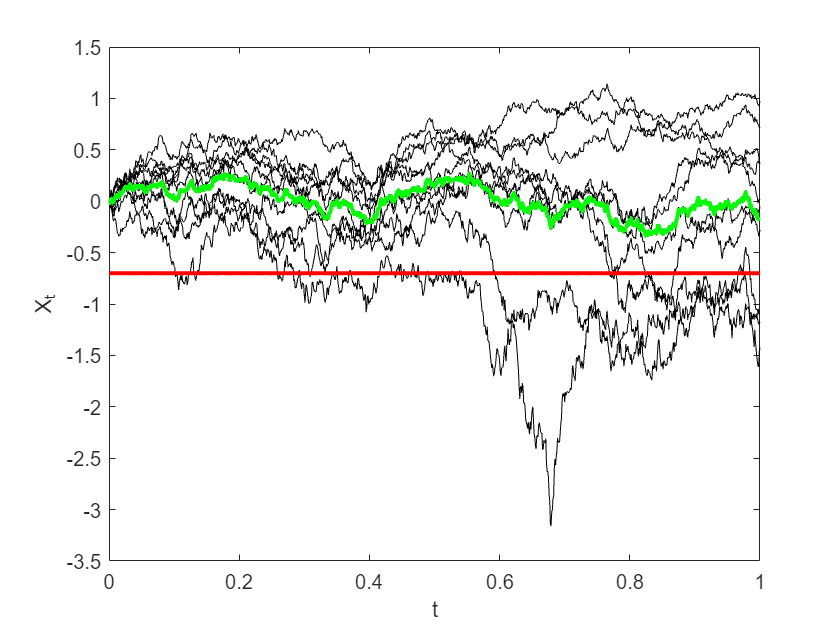

baseline_emcn = baseline.exp_noise(0.5, 0.5, 0.5);
baseline_emcn = baseline_emcn.sde_euler;
baseline_emcn.plot_trajectory;

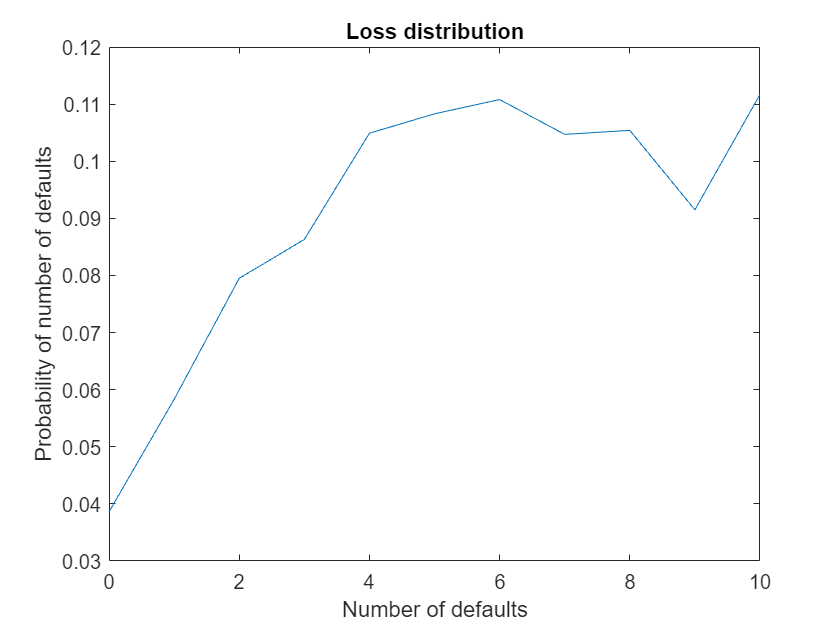

plot_loss(baseline_emcn, 10000);

Large amount of common noise

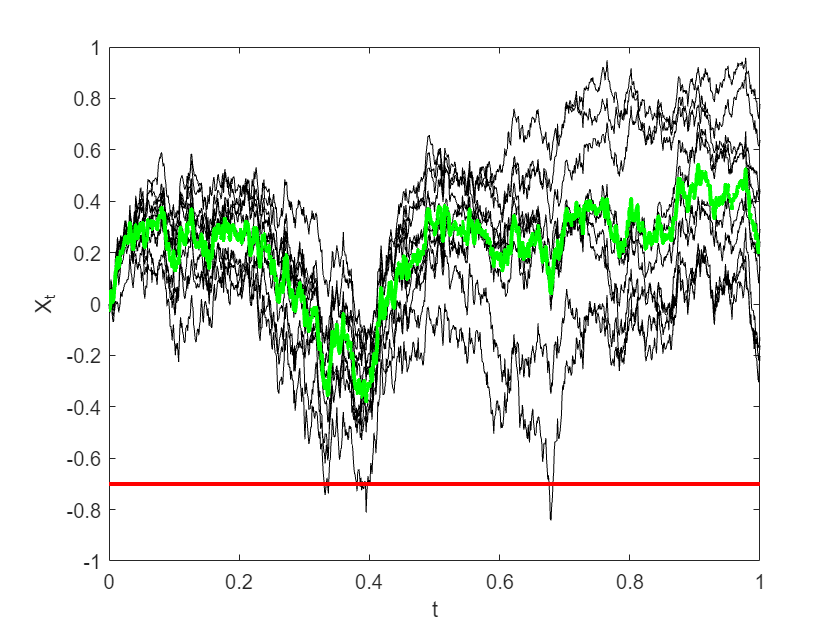

baseline_emcn2 = baseline.exp_noise(0.9, 0.5, 0.5);
baseline_emcn2 = baseline_emcn2.sde_euler;
baseline_emcn2.plot_trajectory;

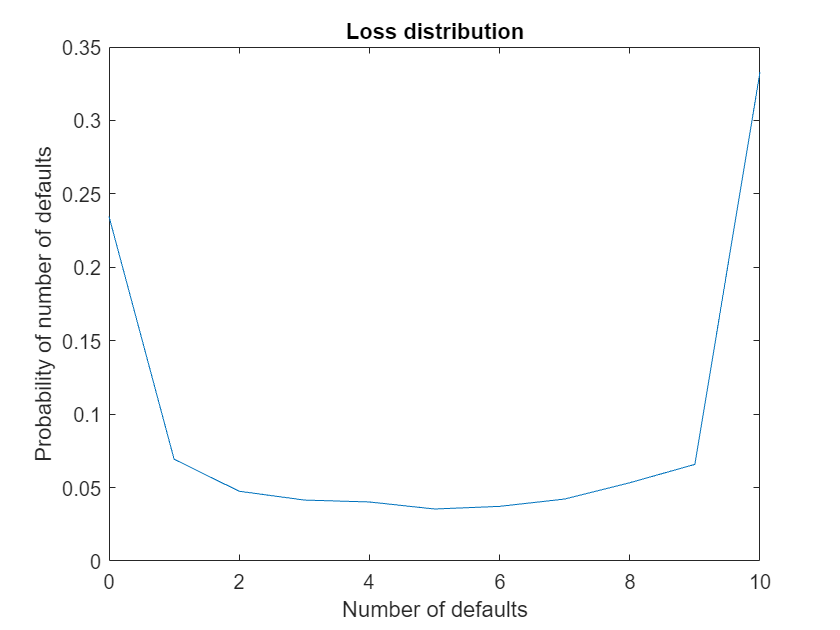

plot_loss(baseline_emcn2, 10000);

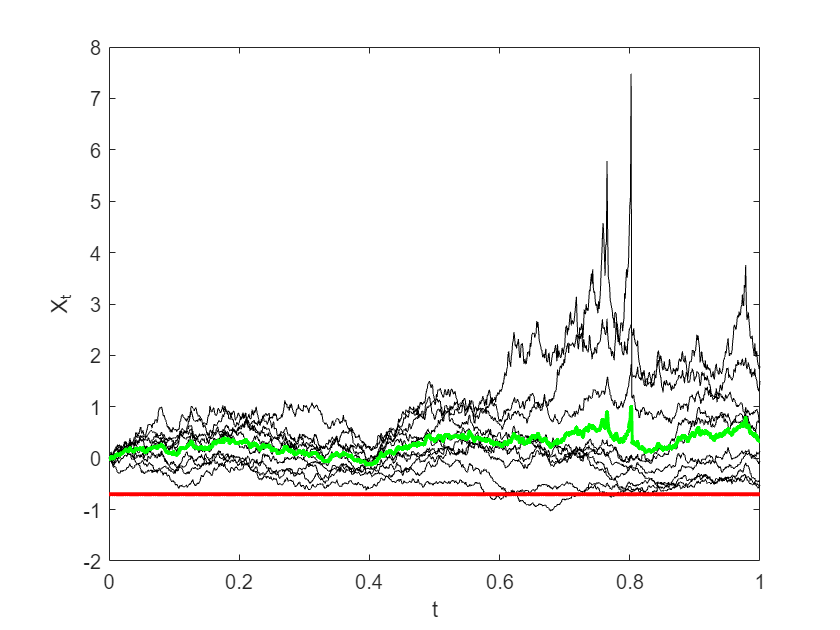

test = baseline.multiplicative_common_noise(0.5, 0.78, 0.5);
test = test.sde_euler;
test.plot_trajectory;